# **Esercitazione 2 - EEG**

**Obiettivo 1: Realizzare una funzione che permetta di caricare automaticamente i dati.**

***reminder: AD è patologico (Alzheimer's disease), C è fisiologico (healthy control)***

%function my_importdata()

%my_importdata;

%per l'implemantazione uso un soggetto per tipo
dir();

.         ad01.mat  ad03.mat  ad05.mat  ad07.mat  ad09.mat  c01.mat   c03.mat   c05.mat   c07.mat   c09.mat   
..        ad02.mat  ad04.mat  ad06.mat  ad08.mat  ad10.mat  c02.mat   c04.mat   c06.mat   c08.mat   c10.mat   



load(strcat('ad01','.mat'))
load(strcat('c01','.mat'))


**Obiettivo 2: Calcolare e visualizzare lo spettro di densità di potenza per ogni dato EEG.**

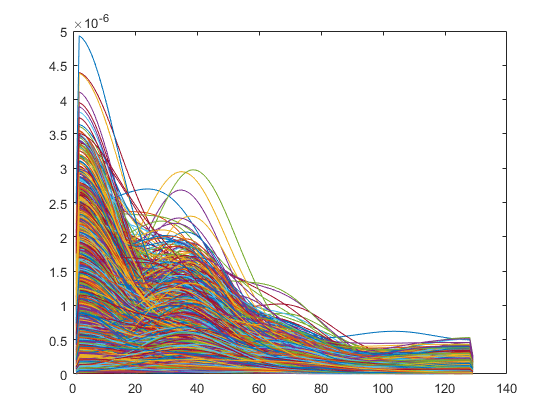

%function my_pwelch(ad01, )


%plot(ad01);
pxx=pwelch(ad01);
plot(pxx);

% Funzione per il calcolo dello spettro di densità di potenza

fs=100

fs = 100

function [PXX, f] = my_pwelch(x,wdw,overlap,nfft,fs)
    %riordino matrice 2d in una 3d
    [n_channels, n_samples]=size(x);
    
    xStart = 1:wdw-overlap:n_samples;
    xEnd= xStart + wdw;
    
    n_wdw=size(xStart, 1);
    %prealloco matrice
    mat_overlap=zeros(n_channels, wdw, n_wdw);
    
    %riempio matrice con il periodogramma
    for idx_wdw=1:lenght(xStart)
       x_final(:,:, idx_wdw)=abs(fft(x(:, xStart(idx_wdw):xEnd(idx_wdw)), [], 2)^2);
    end
    x_final=trapz(3);
    
    %media periodogramma (media rispetto alla terza dimensione)
    x_final=mean (mat_overlap, 3);
    

end

**Obiettivo 3: Calcolare i valori di Potenza Assoluta e Relativa per ogni gruppo.**

%function compute_abs_real_power()

**Obiettivo 4: Visualizzare i valori di Potenza Assoluta e Relativa**